# Modeling Traffic

[⇦ Main Menu](matlab:open('MainMenu.mlx'))

As nearly every driver in a city has experienced, traffic jams are a common feature of modern life. While in some cases, a clear cause of bad weather or an earlier accident can be apparent, in many cases, there is no apparent reason why traffic seems to progress in fits and starts. Changing the behavior of humans is difficult, but perhaps we can change the behavior of cars to mitigate the problems. 

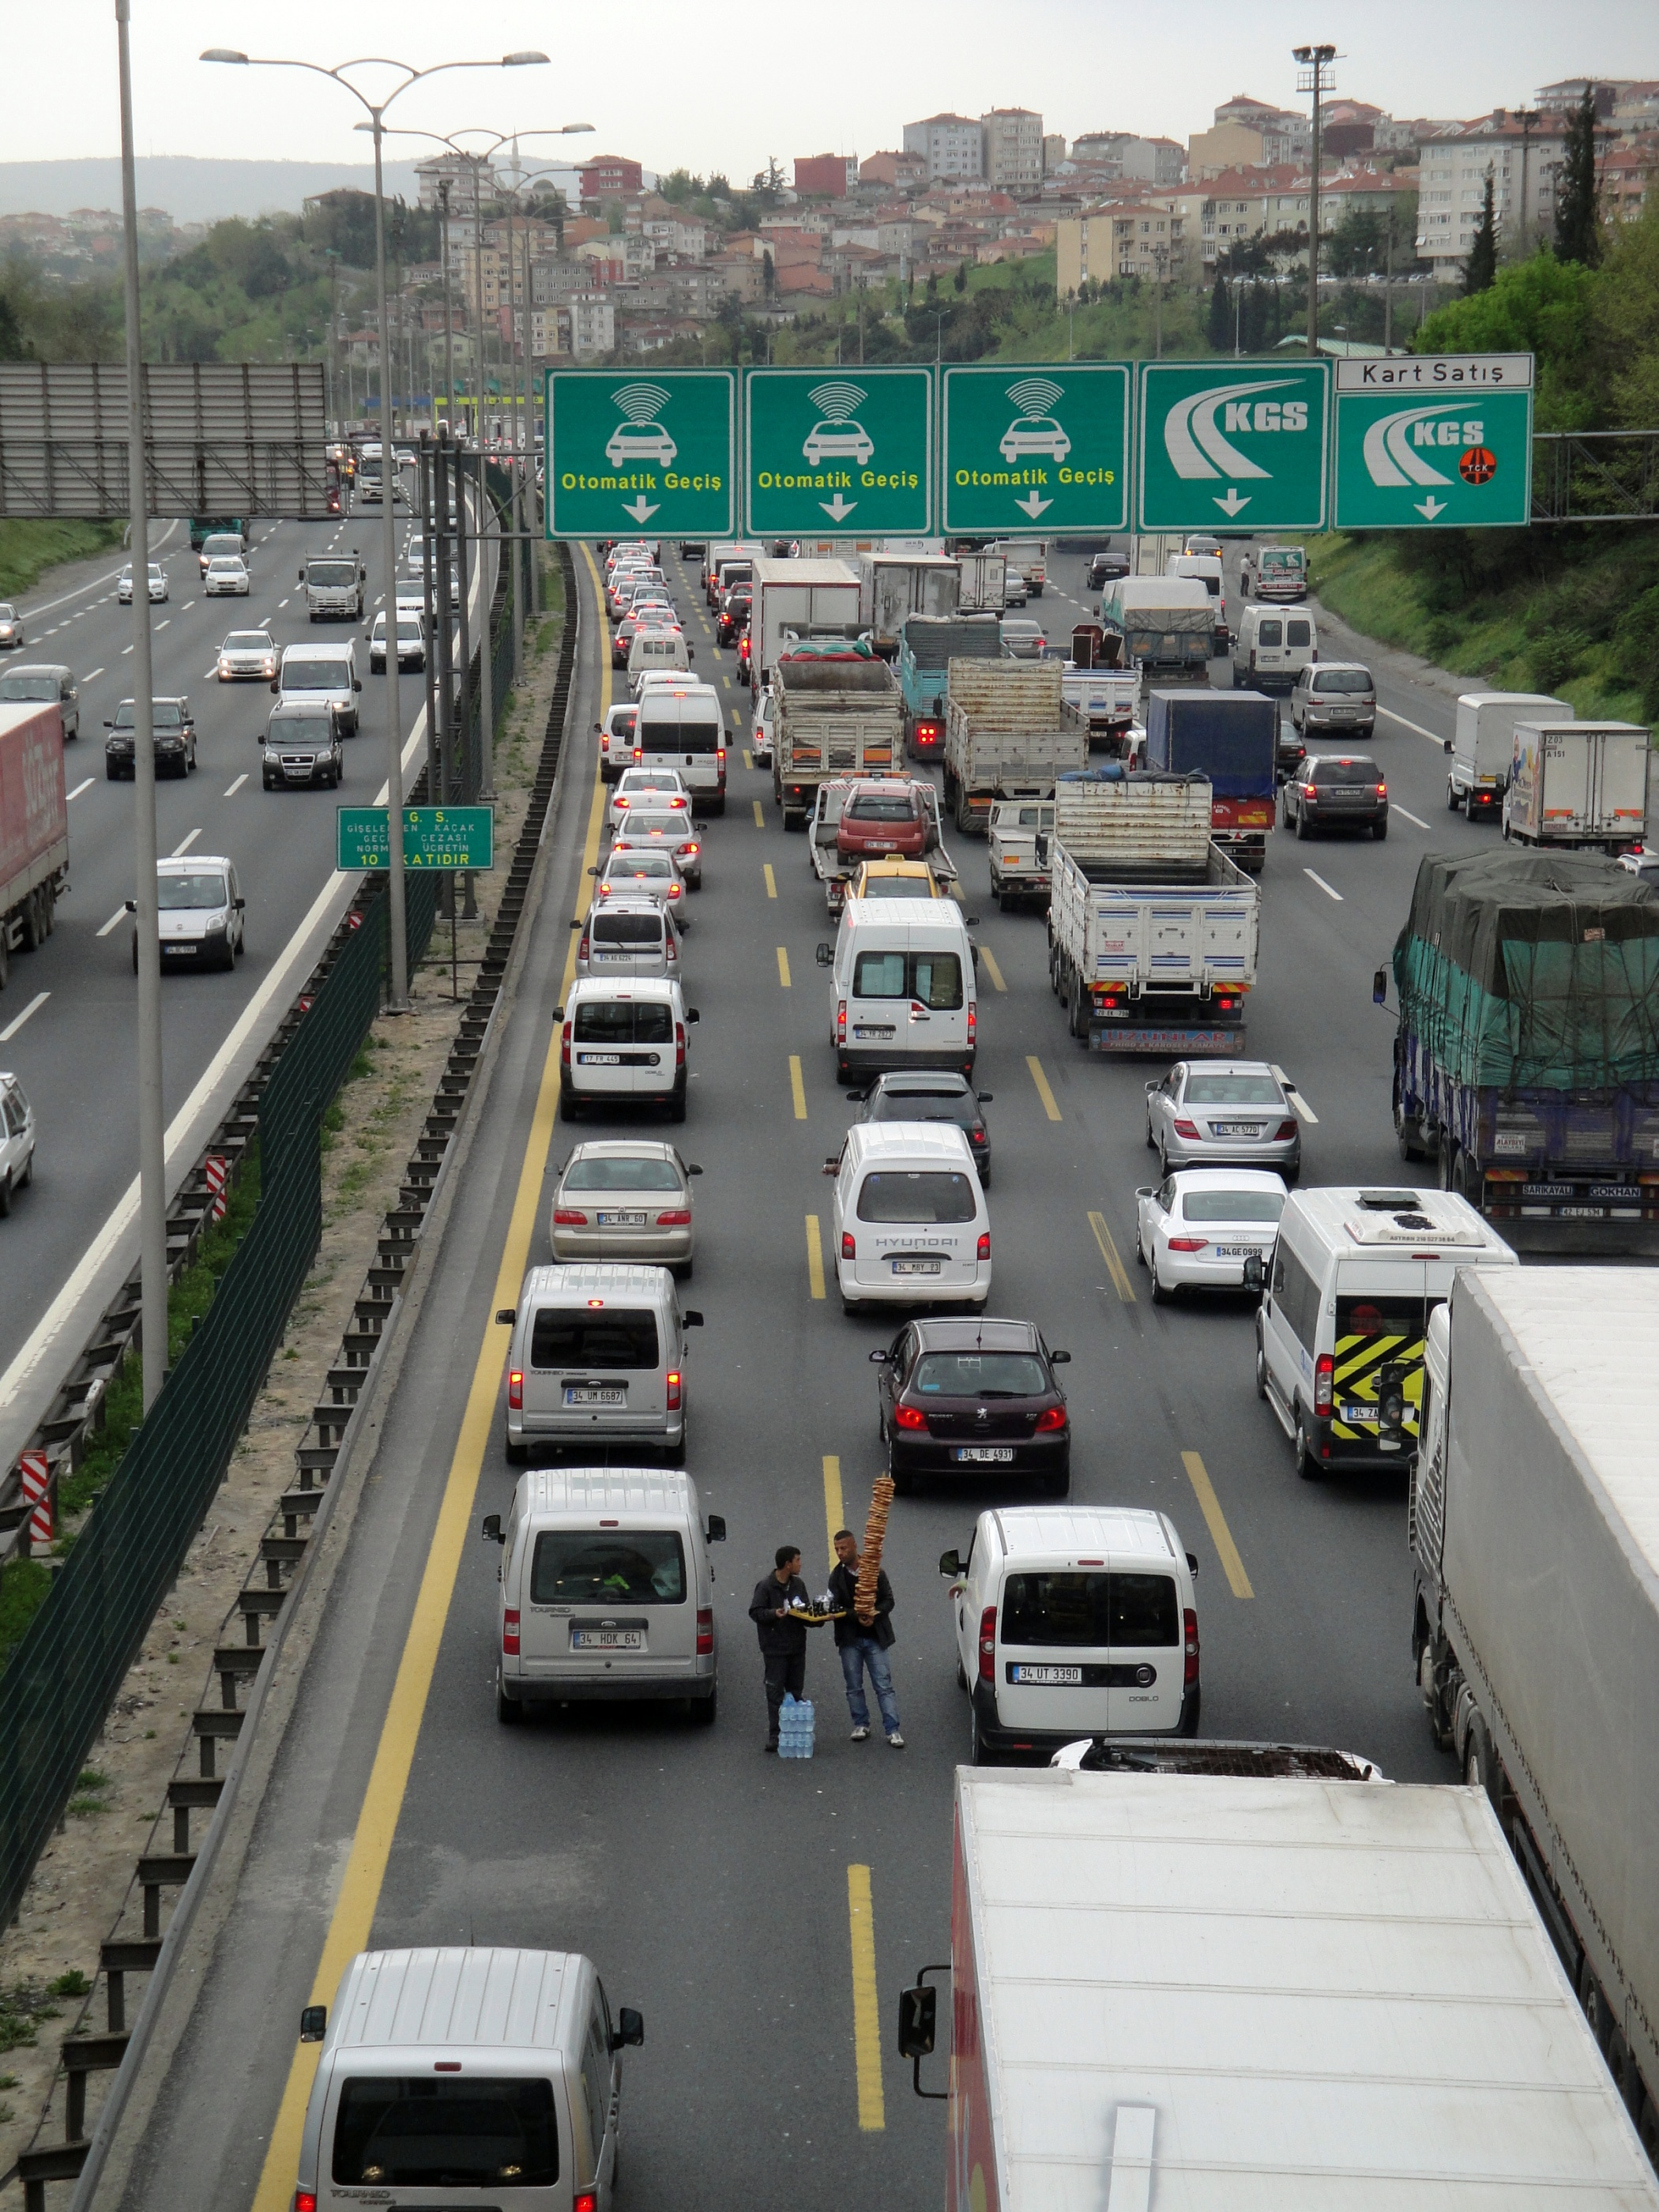

A photograph of Istanbul traffic by [Reise Reise](https://commons.wikimedia.org/wiki/File:Istanbul_Otoyol_2_Richtung_FSM_2.jpg), [CC BY-SA 3.0](https://creativecommons.org/licenses/by-sa/3.0/deed.en)

Modeling traffic as a partial differential equation will allow us to see how traffic jams appear and dissipate. 

## Continuity Equations

One way to describe transport equations is by how they relate to conservation laws. If we require that a quantity is *locally *conserved, we can describe its motion as a continuous flow. This is useful for many physical systems that we conceive as flowing, such as gases or liquids, or even, in a modeling sense, traffic. Fundamentally, we will describe a control region (in one dimension this is just a line segment) from $x=0$ to $x=L$. Let's consider the quantity of momentum, the product of mass density $\rho$ and flow velocity $\vec{u}$.  As we observe the system over time, there can be flow into and out of the system through the ends of our domain at $x=0$ and $x=L$. This corresponds to cars entering or leaving the region of study at various speeds and is called the flux, which is the momentum flowing per unit of time through the point. If $\vec{u}(x,t)$ is the velocity of the cars at point $x$ and time $t$, then the mass flux at that point is $\vec{j}(x,t) = \rho(x,t)\left(\vec{u}(x,t)\right)^2$. We could also include a source term (roadway onramps) and a sink term (roadway exits), but let's begin with a simple closed system, such as a professional car race with a fixed number of competitors driving on a closed course. 


$$\frac{\partial (\rho u)}{\partial t} + \frac{\partial}{\partial x} \left(\rho u^2\right) = 0$$


Applying the product rule, this is:


$$u\frac{\partial \rho}{\partial t} + \rho\frac{\partial u}{\partial t} + u\frac{\partial}{\partial x} (\rho u) + \rho u \frac{\partial u}{\partial x} = 0$$


which simplifies to 

$u \left(\underbrace{\frac{\partial \rho}{\partial t} +\frac{\partial}{\partial x} (\rho u)}_{\text{conservation of mass}}\right) +  \rho\left(\underbrace{\frac{\partial u}{\partial t} +  u \frac{\partial u}{\partial x}}_{\text{1-D nonlinear transport}}\right) = 0$.

However, because mass is conserved, the first term is 0, and since a vehicle's mass density should be non-zero, we can solve the 1-D transport equation we recognize. 

### Adding Dimensions

In higher dimensions, the dimensions of the continuity equation also go up, such as the momentum per unit volume, $\rho(x,y,z,t)\vec{u}(x,y,z,t)$, and the flux $\vec{j} = \rho (\vec{u}\cdot \vec{u})$ is the momentum per unit area per unit time.

## Nonlinear Transport Equation

Consider a simple nonlinear, homogeneous partial differential wave equation:

$\frac{\partial u}{\partial t} + u\frac{\partial u}{\partial x} = 0$.       $(\diamondsuit)$

In this nonlinear equation, however, the transport speed is not uniform but depends on the wave function. The[ characteristic curve method](matlab:open('./MethodOfCharacteristics.mlx')) does allow an approach to solving this equation, although it may be complicated to express the solution analytically. Remember that we assume the curves we are solving for are contour lines of the solution, so the value $u(X(s),T(s))=u(x_0,t_0)=u_0$ along each curve. This means that the value of $u$ is a constant along each characteristic curve, which reduces Equation $(\diamondsuit)$ to a (potentially different) constant speed wave equation along trajectories passing through each initial value. 

  **Try**. What do these characteristic plots look like with different initial values?

clear t x u
syms t x u
tCoeff = 1;
xCoeff = u;
uCoeff = 0;
jumppoint = -1;
speed = 0.5;    % absolute value of velocity
f(x,t) = exp(-x^2); IC = "gaussian";     
t0 = 0;
InitialCond(x) = f(x,t0);
PlotInitialData(-6,4,f=InitialCond,Label=IC);
[~,xEqn1,uSol] = SolveCharacteristicEquationNonlinear(InitialCond,tCoeff,xCoeff,uCoeff,t0,PrintSoln=true);

This means that the solution looks like:

 
tValues = [t0:0.05:3 t0:-0.05:-1];
xValues = -10:0.15:10;
xLimits = [-7 7];
PlotCharacteristicCurves(tValues,xValues,InitialCond,xEqn1,xLimits,NumColors=20,animate=false);

Remember that the color represents the value of the solution at that point on the $(t,x)$ plane. Each constant-value contour curve is the same color.

## Locating and Resolving Rarefaction Regions

A rarefaction region occurs when a region in the positive time characteristic plot does not have any characteristic curves passing through it. This corresponds to the example in [MethodOfCharacteristics](matlab:open('./MethodOfCharacteristics.mlx')): Nonlinear Transport Equation with a step up. Recall that the solution corresponding to a characteristic plot with an (unresolved) rarefaction region looks like:

 
AnimateRarefaction(-1,2)

 **Exercise 1. **For each initial condition above, check the corresponding box if the characteristic plot displays a rarefaction region:

Gaussian = false; Trigonometric = false; Sinusoidal = false; GreenLight = false; RedLight = false;
 
CheckExercise1(Gaussian,Trigonometric,Sinusoidal,GreenLight,RedLight,jumppoint,abs(speed)) % Trying to add plot

A rarefaction will always have a point $(t_{\star},x_{\star})$ where the region begins. We can also define the characteristic curves that bound the region as $x\text{Plus}(t)$ giving the upper boundary and $x\text{Minus}(t)$ giving the lower boundary.

  **Exercise 2. **

Select an initial condition that generates a rarefaction region and identify the relevant values and functions.

ICChoice = "gaussian";

These values should be numbers:

tStar = 0;
xStar = 0;

Identify the equations that bound the rarefaction region. These values should be functions of $t$.

xPlus =  t;
xMinus = t;
 
CheckExercise2(ICChoice,tStar,xStar,xPlus,xMinus,jumppoint,abs(speed))

### Resolving Rarefaction Regions

The most physically realistic way to resolve a rarefaction region is to fill it with a rarefaction fan that interpolates values of the solution across the 'empty' space. With this assumption, the interpolated value of $u(x,t)$ can be worked out from our assumptions when solving the equation. Because our parameter $s=t$, the condition that $\frac{dx}{ds} = u$ is also the statement that $\frac{dx}{dt} = u$. Therefore, we can compute the slope of our characteristic curve at a point, which must be the value of $u(x,t)$ at that point.

 
if ICChoice == "green"
    syms x t u0 x0
    if ~exist("jumppoint","var")
        jumppoint = -1;
        speed = 2;
        t0 = 0;
    end
    % InitialCondGreen(x) = piecewise(x<jumppoint,0,abs(speed));
    InitialCondGreen(x) = abs(speed)*heaviside(x-jumppoint)*(1-kroneckerDelta(x-jumppoint));
    xEqnGreen = x==x0+t*u0;
    uSolGreen(x,t,u0) = piecewise(x - t*u0 < jumppoint, 0, symtrue, abs(speed));
    x1Green(t) = jumppoint + abs(speed)*t;
    x2Green(t) = jumppoint + 0*t;
    tValues = [t0:0.05:3 t0:-0.05:-1];
    xValues = -10:0.15:10;
    xLimits = [-3 4];
    ax = PlotCharacteristicCurves(tValues,xValues,InitialCondGreen, ...
        xEqnGreen,xLimits,NumColors=20,animate=false);
    hold on
    DrawRarefactionCurves(ax,0,jumppoint,x1Green,x2Green,15,0,abs(speed))
    hold off
    PlotSolutionWithRarefaction([t0 3], [-7 7],InitialCondGreen,rhs(xEqnGreen),0, ...
        xLimRange=xLimits,xPlus=x1Green,xMinus=x2Green)
else
    disp("Please select initial conditions that generate a rarefaction.")
end

 **Reflect**. 

- What does this approach look like if the initial condition is $u(x,0) = \cases{0 & x<0 \cr 1+x & x\geq 0} $?

- Can you modify this approach to solve an equation of the form $\frac{\partial u}{\partial t} + u^2\frac{\partial u}{\partial x} = 0, $ with the initial condition $u(x,0) = \cases{0 & x<-1 \cr 2 & x \geq -1}$? 

## Locating Shock Regions

Say $u = f(x_0)$ along characteristic curves. A shock occurs in the region where our characteristic curves predict multiple values of the solution. To define the shock region, we need to locate where the shock starts. Then, we will be able to propagate the shock forward in time. The shock occurs when the slope of the solution becomes undefined, as at a piecewise discontinuity or by approaching $-\infty$. Recall the first-order time-dependent PDE:

           
$$\frac{\partial u}{\partial t} + u\frac{\partial u}{\partial x} = 0$$
           
$$(\diamond)$$


  
$$u(x,t_0) = f(x)$$


Let's consider the function $\frac{\partial u}{\partial x} = \frac{\text{d}f}{\text{d}x_0}\frac{\partial x_0}{\partial x}$. We have computed that $x_0=x-tu$, so we can compute 


$$\frac{\partial x_0}{\partial x}=1-t\frac{\partial u}{\partial x}$$
 

so 

$\frac{\partial u}{\partial x}\left(1+t f'(x_0)\right) = f'(x_0)$    $\Rightarrow$      $\frac{\partial u}{\partial x} = \frac{f'(x_0)}{1+tf'(x_0)}$.  

This rate of change will blow up (diverge to infinity) if $tf'(x_0) \to -1$, or in other words, as $t \to -\frac{1}{f'(x_0)}$. Thus, we locate the shock discontinuity at the earliest time this value is achieved:


$$t_{\star} = \min\left\{-\frac{1}{f'(y)}~|~f'(y)<0\right\}$$


and, if $y_{\star}$ is the value such that $t_{\star} = -\frac{1}{f'(y_{\star})}$, then $x_{\star} = y_{\star} + f(y_{\star})t_{\star}$.

  **Exercise 3.** Select an initial condition that exhibits a shock and compute the starting point for the shock. 

jumppoint = -1;
speed = 2;
f(x,t) = exp(-x^2); IC = "gaussian";
t0 = 0;
syms x
ICf(x) = f(x,t0);
displayFormula("f(x) == ICf")
 
[~,xEqnShock,uSolShock] = SolveCharacteristicEquationNonlinear(f,1,u,0,t0,PrintSoln=false);
tValues = [t0:0.05:3 t0:-0.05:-1];
xValues = -11:0.15:7;
xLimits = [-5 7];
PlotCharacteristicCurves(tValues,xValues,ICf,xEqnShock,xLimits,NumColors=20,animate=false);

**Note:** Some choices generate much easier calculations than others. If you are struggling with the computations, try a different shock.

yStar =  0;
tStar =  0;
xStar =  0;

PassedEx3 = CheckExercise3(yStar,tStar,xStar,IC,ICf,jumppoint);
 
if PassedEx3
    ax3 = PlotCharacteristicCurves(-1:.02:3,-10:.2:8,ICf,xEqnShock,[-5 7],NumColors=15,animate=false);
    hold on
    [x1,x2,tShockVals,tShockIdx,yPlus,yMinus] = ShadeShockRegion(ax3,tStar,xStar,rhs(xEqnShock),ICf,uSolShock,x0Star=yStar);
    hold off
end

### Resolving a Shock

Once we have identified where a shock begins, we still need to calculate how the shock will travel. Unlike the rarefaction waves, this calculation will require additional information about the physical constraints of our system because, mathematically, there is an infinite family of possible solutions. Whether any such shocks could exist in the physical world was argued over by mathematicians and the occasional engineer for centuries (see, for example, [2]). Let us call the shock $\sigma(t)$. Then we know that $\sigma(t_{\star}) = x_{\star}$ is an initial condition. The question that remains is how to define $\frac{d\sigma}{dt}$.

We shall employ a simplified jump condition $\frac{d\sigma}{dt} = \frac{X^+-X^-}{T^+-T^-}$ with $X^+(t) = \lim_{x\to\sigma^+}X(x,t)$, $T^-(t) = \lim_{x\to\sigma^-}T(x,t)$, and so forth, and where $T$ and $X$ are any functions satisfying $\frac{\partial T}{\partial t} + \frac{\partial X}{\partial x} = 0$,  Note that one mathematically acceptable choice is $T=u$ and $X=\frac{1}{2}u^2$. 

 **Reflect**. 

- Why does $T=u$ and $X=\frac{1}{2}u^2$ work?

- What constraints might matter beyond mathematics?

 
if exist("PassedEx3","var") && PassedEx3
    tVals = linspace(t0,3,100);
    xVals = -10:0.2:10;
    xLimitValues = [-4 6];
    [xShock,uPlus,uMinus] = SolveShock(tShockVals,tShockIdx,xStar,yPlus,yMinus,ICf,T=u,X=1/2*u^2);
    ax = PlotCharacteristicCurves(tVals,xVals,ICf,xEqnShock,xLimitValues, ...
        DrawShock=true,ShockTimes=tShockVals,ShockVals=xShock);
    hold on
    plot(ax,tShockVals,xShock,LineWidth=3,SeriesIndex="none")
    hold off
else
    disp("You must complete Exercise 3 before plotting the result.")
end

## **References**

**[1] **Lighthill, M. J., & Whitham, G. B. (1955). On kinematic waves II. A theory of traffic flow on long crowded roads. *Proceedings of the Royal Society of London. Series A. Mathematical and Physical Sciences*, *229*(1178), 317-345. [https://doi.org/10.1098/rspa.1955.0089](https://doi.org/10.1098/rspa.1955.0089)

[2] Salas, M. D. (2006, September 4). *The Curious Events Leading to the Theory of Shock Waves* [Invited lecture]. Shock Interaction Symposium. [https://ntrs.nasa.gov/api/citations/20060047586/downloads/20060047586.pdf](https://ntrs.nasa.gov/api/citations/20060047586/downloads/20060047586.pdf) 

## Further Exploration

To go deeper with this model, you want to explore [weak solutions](https://en.wikipedia.org/wiki/Weak_solution) to partial differential equations and the physically realized version of the[ Rankine-Hugoniot equations](https://en.wikipedia.org/wiki/Rankine%E2%80%93Hugoniot_conditions) that doesn't satisfy one randomly chosen conservation law but all three primary conservation laws: mass, momentum, and energy. 

[⇦ Return to the main menu](matlab:open('MainMenu.mlx'))

## Local Helper Functions

If you want to see the details of the code, select the **View** tab and switch to **Output Inline**. Alternately, select **Output inline **using the icon   at the top right of the Live Editor pane.

function ExplainSolution(f,a,b,c,t0,dtds,tEqn,sEqn,duds,UEqn,UEqn2,dxds,xEqn2,CharCurve,CharSoln)
syms t x u T(s) X(s) U(s)
syms u(x,t) uSol(x,t,u0) T(s) X(s) U(s) s t x x0 u0 F(x)

F(x) = f;
displayFormula("'The partial differential equation is:'")
displayFormula("a*diff(u,t)+c*diff(u,x)+b == 0")
displayFormula(["'with initial data: '" "u(x,t0)==F"])
displayFormula(["'By choosing '" "s" "' to represent the parametric variable, we can write: '" ...
    "U(s) == u(x,t)"  "', and '" "T(s) == t" "', and '" "X(s) == x" "'.'"])
displayFormula(["'By solving '" "dtds" "' with '" "T(0)==t0" "' we calculate that '" "tEqn" "','"])
displayFormula(["'and therefore '" "s == sEqn" "'.'"])
displayFormula(["'By solving '" "duds" "' with '" "U(0)==u0" "' we have '" "UEqn"])
displayFormula(["'and plugging in our expression for '" "s" "', we see that: '" "UEqn2" "'.'"])
displayFormula(["'and by solving '" "dxds" "' with '" "X(0)==x0" "' we calculate that '" "xEqn2" "'.'"])
displayFormula(["'Therefore, the characteristic value is '"  "x0 == CharCurve.x0"  "','"])
displayFormula(["'and the solution is '" ; "CharSoln" ])
end

function [tEqn,xEqn2,uSol] = SolveCharacteristicEquationNonlinear(f,a,c,b,t0,opts)
% This function solves equations of the form
% a(t)*diff(u,t)+c(u)*diff(u,x)-b = 0
% with the initial condition u(x,t0) = f(x)
arguments
    f
    a
    c
    b
    t0
    opts.ShowConditions = false
    opts.PrintSoln = true
end
% Create functions for each coefficient a, c, b
if class(c)=="sym"
    syms t x u T(s) X(s) u0
    B = subs(c,[t x u],[T X u0]);
else
    B = c;
end

if class(a)=="sym"
    syms t x u T(s) X(s) u0
    A = subs(a,[t x u],[T X u0]);
else
    A = a;

end

if class(b)=="sym"
    syms t x u T(s) X(s) U(s)
    C = subs(b,[t x u],[T X U]);
else
    C = b;
end

syms u(x,t) uSol(x,t,u0) T(s) X(s) U(s) s t x x0 u0 F(x)

% % Name the initial condition function
F(x) = f;

% Time is a real variable
assume(t,"real")

% Solve the ODE for t as a function of the parameter s. If this is not
% solvable, give up on this method for now.
dtds = diff(T,s)==A;
tEqn = t == dsolve(dtds,T(0)==t0);
sEqn = solve(tEqn,s);

% Solve the ODE for u as a function of the characteristic variable x0 along
% characteristic curves parametrized by s.
duds = diff(U,s) == -subs(C,T,rhs(tEqn));
UEqn = u == dsolve(duds,U(0)==u0);
UEqn2 = subs(UEqn,s,sEqn);

% Solve the ODE for x as a function of s.
dxds = diff(X,s)==subs(B,T,rhs(tEqn));
xEqn = x == dsolve(dxds,X(0)==x0);
xEqn2 = subs(xEqn,s,sEqn);
CharCurve = solve(xEqn2,x0,"ReturnConditions",true);
U0 = F(CharCurve.x0);
%CharSoln(x,t,u0) = simplify(subs(F(subs(CharCurve.x0,t0,0))+subs(rhs(UEqn)-u0,[T X],[rhs(tEqn) rhs(xEqn3)]),s,sEqn));

CharSoln =  subs(UEqn2,u0,U0);
uSol(x,t,u0) = rhs(CharSoln);

if opts.PrintSoln
    ExplainSolution(f,a,b,c,t0,dtds,tEqn,sEqn,duds,UEqn,UEqn2,dxds,xEqn2,CharCurve,CharSoln)
end
if opts.ShowConditions
    displayFormula("CharCurve.conditions")
end
end


function p = PlotInitialData(xMinVal,xMaxVal,opts)
arguments
    xMinVal (1,1) double
    xMaxVal (1,1) double
    opts.f
    opts.Label (1,1) string {mustBeMember(opts.Label,["trigonometric" "sinusoidal" "red" "green" "gaussian"])} = string.empty;
end
figure
p = fplot(opts.f,[xMinVal xMaxVal]);
if isempty(opts.Label)
    title("The initial data")
else
    switch opts.Label
        case "sinusoidal"
            title("Traffic that moves periodically faster and slower")
            subtitle("$f(x) = " + string(latex(opts.f)) + "$",Interpreter="latex")
        case "trigonometric"
            title("Traffic that decelerates from a fixed travel speed")
            subtitle("$f(x) = " + string(latex(opts.f)) + "$",Interpreter="latex")
        case "red"
            title("Traffic that comes up to a red light and stops")
            subtitle("f(x) = " + string(opts.f),Interpreter="none")
        case "green"
            title("Traffic that starts from a stop when a light turns green")
            subtitle("f(x) = " + string(opts.f),Interpreter="none")
        case "gaussian"
            title("Traffic that accelerates and then decelerates")
            subtitle("$f(x) = " + string(latex(opts.f)) + "$",Interpreter="latex")
    end
end

xlabel("$x$",Interpreter="latex")
ylabel("$u(x,t)$",Interpreter="latex")
end



function CheckExercise1(a2,a3,a4,a5,a6,pt,spd)
Solution = [a2 a3 a4 a5 a6];
if all(Solution == [false false false true false])
    disp("That is correct." + newline + ...
        "The only initial condition in this set that generates a rarefaction region is the green light." + newline + ...
        "The space-time point where the rarefaction region begins is identified by a star.")
    fill([0 1 1 0],[pt pt pt+spd pt],[0.6384 0.9910 0.2365])
    ax = gca;
    ax.XLim = [0 1];
    if spd > 0
        ax.YLim = [pt-1 pt+spd+1];
    else
        ax.YLim = [pt+spd-1 pt+1];
    end
    hold on
    val = max(10,ceil(abs(spd)*20));
    k = (1:val)';
    plot(ax,[0 1],[pt-k*.1 pt-k*.1],Color=[0.1900 0.0718 0.2322])
    plot(ax,[0 1],[pt+k*.1 pt+k*.1+spd],Color=[0.4796 0.0158 0.0106])
    plot(ax,[0 1],[pt pt+spd],SeriesIndex=1,LineWidth=2)
    plot(ax,[0 1],[pt pt], SeriesIndex=2,LineWidth=2)
    scatter(ax,0,pt,MarkerFaceColor=[1 0 0],Marker="pentagram",SizeData=70)
    hold off
    legend(ax,ax.Children(1:3),["(t_{star},x_{star})" "xMinus(t)" "xPlus(t)"],Location="northwest")
    disp("The filled region identifies the space-time values where" + newline ...
        + "there are no paths back to the initial conditions, and "+ newline ...
        +"therefore no solutions in this region:")
    disp("To resolve the rarefaction, define solutions in this region.")
end

if a2
    disp("No, there is no rarefaction with the Gaussian initial condition.")
end
if a3
    disp("No, there is no rarefaction with the trigonometric initial condition.")
end
if a4
    disp("No, there is no rarefaction with the sinusoidal initial condition.")
end
if ~a5
    disp("Is there an empty region with the green light initial condition?")
end
if a6
    disp("No, there is no rarefaction with the red light initial condition.")
end

end

function CheckExercise2(IC,tStar,xStar,xP,xM,pt,spd)
flag = 1;
if IC ~= "green"
    disp("Did you complete Exercise 1? Where are there rarefactions?")
else
    if tStar~=0
        disp("When does the rarefaction region start? Check the intersection of $x^+(t)$ and $x^-(t)$.")
        flag = 0;
    else
        displayFormula('"tStar looks correct."')
    end
    if xStar ~= pt
        disp("What is the value of $x_{\star}$? It is not " + xStar +".")
        flag = 0;
    else
        displayFormula('"xStar looks correct."')
    end
    syms t
    xPlus(t) = sym(xP);
    xMinus(t) = sym(xM);

    if ~isAlways(xPlus(t)==pt+spd*t,"Unknown","false")
        wrongAns = sym(xP);
        displayFormula(['"No, "' "xPlus(t) == wrongAns" '" is incorrect."'])
        displayFormula('"What is the function that bounds the top of the rarefaction region?"')
        flag = 0;
    else
        displayFormula(['"Yes, "' "xPlus(t)==pt+spd*t" '" is correct."'])
    end

    if ~isAlways(xMinus(t)==pt,"Unknown","false")
        wrongAns = sym(xM);
        displayFormula(['"No, "' "xMinus(t) == wrongAns" '" is incorrect."'])
        displayFormula('"What is the function that bounds the bottom of the rarefaction region?"')
        flag = 0;
    else
        displayFormula(['"Yes, "' "xMinus(t)==pt" '" is correct."'])
    end
    if flag == 1
        displayFormula('"Exercise 2 is correct, please continue."')
    end
end
end

function flag = CheckExercise3(yStar,tStar,xStar,IC,f,pt)
flag = 1;
switch IC
    case "triangle"
        sol = [0 1]; %yStar tStar
    case "gaussian"
        sol = [1/sqrt(2) 1/(sqrt(2)*exp(-1/2))];
    case "trigonometric"
        sol = [0 1];
    case "sinusoidal"
        yStar = mod(yStar,2*pi);
        sol = [pi 1];
    case "red"
        sol = [pt 0];
    case "green"
        disp("This initial data does not generate a shock.")
        flag = 0;
        return
end
syms x
f(x) = f;

solXStar = sol(1) + f(sol(1))*sol(2);

if abs(yStar-sol(1))<1e-4
    disp("Yes, that is within tolerance for yStar.")
else
    disp("Please recalculate yStar and minimize rounding.")
    flag = 0;
end

if abs(tStar-sol(2))<1e-4
    disp("Yes, that is within tolerance for tStar.")
else
    disp("Please recalculate tStar and minimize rounding.")
    flag = 0;
end

if abs(xStar-solXStar)<1e-4
    disp("Yes, that is within tolerance for xStar.")
else
    disp("Please recalculate xStar and minimize rounding.")
    flag = 0;
end

end

